# AMECH Quiz 1 Take-Home

**1.**

b dimensional analysis:


$$\begin{array}{l}
\overset{\ldotp \ldotp }{\phi} =-\omega_0^2 \sin \phi -b\overset{\ldotp }{\phi} \\
\omega_0^2 =\frac{g}{l}\frac{M-m}{M+m}\\
\mathrm{units}\;\mathrm{of}\;\omega_0^2 \;\mathrm{are}\;\frac{1}{s^2 }\\
\frac{\mathrm{rad}}{s^2 }=\left(\frac{1}{s^2 }\right)-b\left(\frac{\mathrm{rad}}{s}\right)\\
\mathrm{rad}=-b\left(\frac{\mathrm{rad}}{s}\right)s^2 \\
\mathrm{rad}=-b\left(\mathrm{rad}\cdot s\right)\\
b\;\mathrm{has}\;\mathrm{to}\;\mathrm{have}\;\mathrm{units}\;\mathrm{of}\;\frac{1}{s}
\end{array}$$


**A & B**

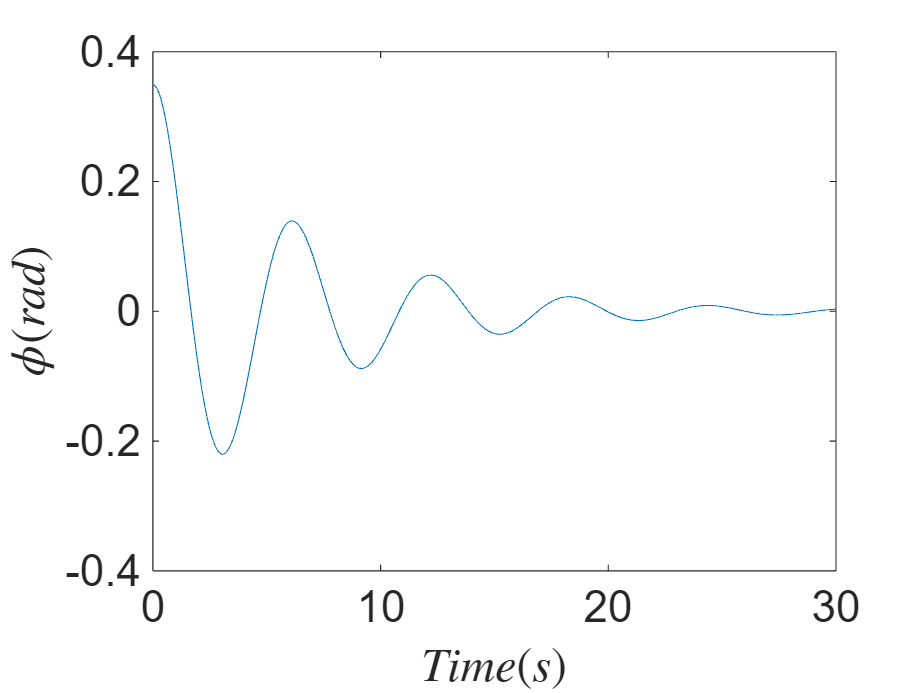

% Function returning a state function of phidot to be use for ode45
function phidot = odefun(t, phi)
    % Initial Variables
    g = 9.8 ; % gravity (m/s^2)
    l = 3 ; % half length of rod (m)
    M = 1 ; % heavier mass attached to one end (kg)
    m = 0.5 ; % lighter mass attached to the other end (kg)
    omegasq = (g/l)*((M-m)/(M+m)) ; % (1/s^2)
    b = 0.3 ; % damping constant (1/s)
    % Set state varible for phi dot
    phidot(1) = phi(2) ; % phi dot
    phidot(2) = -omegasq*sin(phi(1)) - b*phi(2) ; % phi double dot
    phidot = phidot' ;
end
% Initial Varibles
iphi = [deg2rad(20), 0] ; % [initial phi, initial, phi dot]
tspan = linspace(0, 30, 1000) ; % time span (s)
[t, phi] = ode45(@odefun, tspan, iphi) ; % solve ode
% Plot t vs phi 
plot(t, phi(:, 1))
% Plot settings
set(gca, 'fontsize', 20)
xlabel('$Time (s)$', 'Interpreter', 'Latex')
ylabel('$\phi (rad)$', 'Interpreter', 'Latex')
ylim([-0.4, 0.4])

**C.**

This oscillation shows underdampening (b < 0), the oscialltions still occur but eventually reach a point of only small oscillations. Critically dampened would show less oscillations and overdampened would show no oscillations.

**D.**

The equation for the envelope would be the solution for phi without its oscillatory part so,


$$\begin{array}{l}
\mathrm{For}\;\mathrm{underdamped},\\
x\left(t\right)=\mathrm{Ccos}\left(\Omega t+\alpha \right)e^{-\gamma t} \\
\mathrm{so},\\
\phi_{\mathrm{envelope}} \left(t\right)=\frac{\phi \left(t\right)}{\cos \left(\Omega t+\alpha \right)}={\mathrm{Ce}}^{-\gamma t} \\
\mathrm{where}\;\gamma =\frac{b}{2}\;\mathrm{is}\;\mathrm{the}\;\mathrm{damping}\;\mathrm{constant}
\end{array}$$


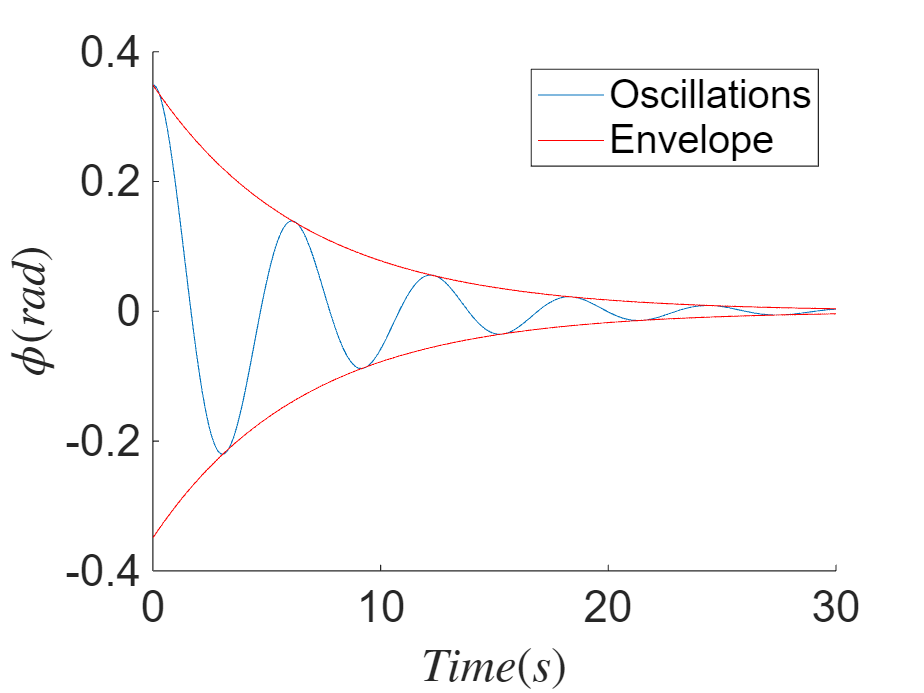

clf
% Initial Variables
g = 9.8 ; % gravity (m/s^2)
l = 3 ; % half length of rod (m)
M = 1 ; % heavier mass attached to one end (kg)
m = 0.5 ; % lighter mass attached to the other end (kg)
omegasq = (g/l)*((M-m)/(M+m)) ; % (1/s^2)
b = 0.3 ; % damping constant (1/s)
% Plot upper and lower envelope pieces on top of oscillator
hold on
plot(t, phi(:, 1))
plot(t, deg2rad(20)*exp(-(b/2).*t), 'r') % Equation above where C is initial amplitude
plot(t, -deg2rad(20)*exp(-(b/2).*t), 'r')
set(gca, 'fontsize', 20)
xlabel('$Time (s)$', 'Interpreter', 'Latex')
ylabel('$\phi (rad)$', 'Interpreter', 'Latex')
ylim([-0.4, 0.4])
legend('Oscillations', 'Envelope')

another way this could be done is by taking the peaks of each oscillations and data points and fitting a function to those peaks.